# Chapter 5 电容电流反馈

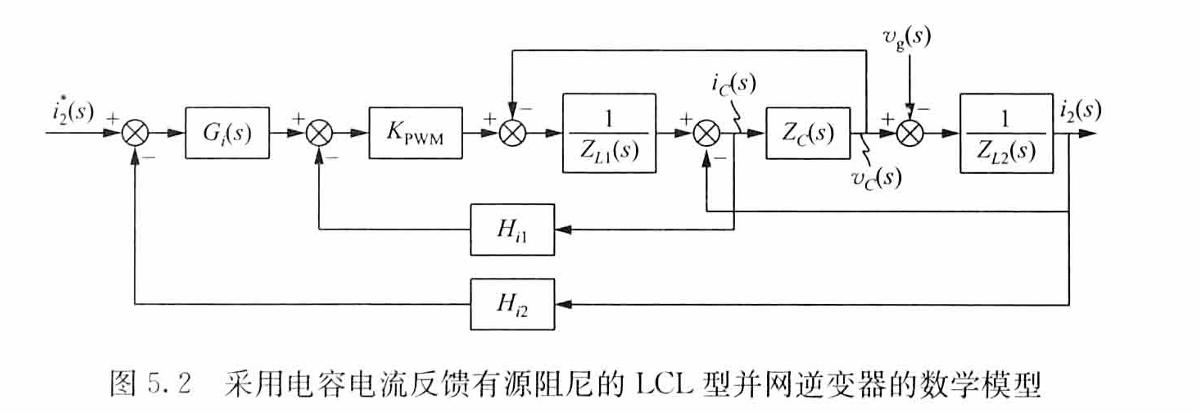

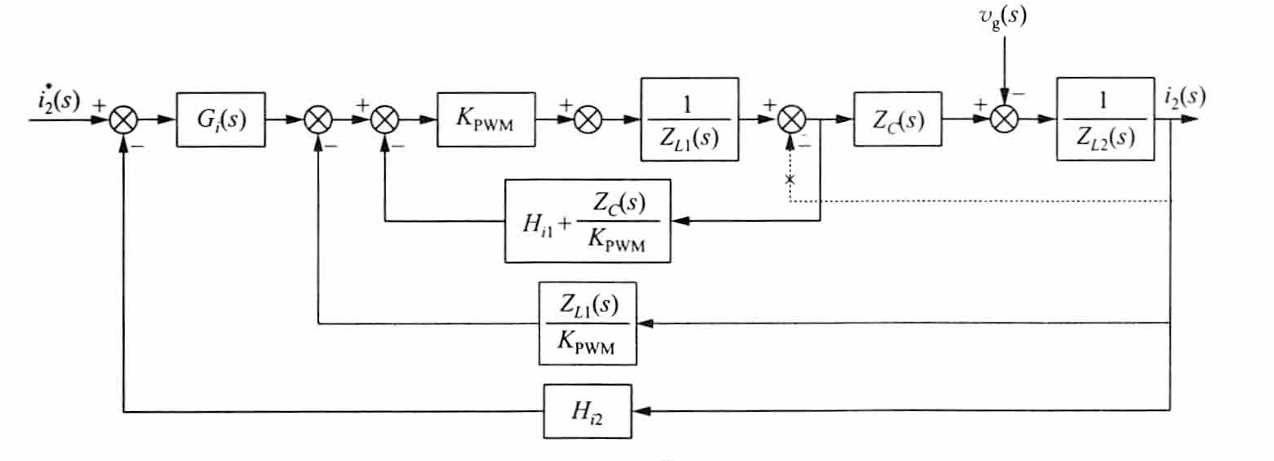

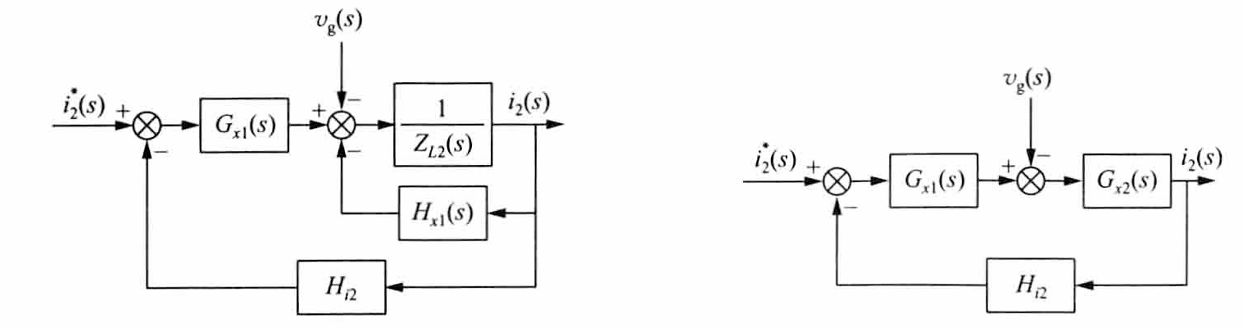

Name the middle loop as G1:


$$G_{1} = \frac{K_{PWM}/Z_{L1}(s)}{1+(H_{i1}+Z_C(s)/K_{PWM})K_{PWM}/Z_{L1}(s)} =  \frac{K_{PWM}}{Z_{L1}+H_{i1}K_{PWM}+Z_C(s)}$$


We have


$$H_{x1} = \frac{Z_{L1}(s)}{K_{PWM}}G_1Z_C = \frac{Z_{L1}(s)Z_C(s)}{Z_{L1}(s) + H_{i1}K_{PWM}+Z_C(s)}$$



$$G_{x1} = G_i(s)G_1(s)Z_C(s) =  \frac{K_{PWM}G_{i}(s)Z_C(s)}{Z_{L1}(s) + H_{i1}K_{PWM}+Z_C(s)}$$


In order to simplify, name the loop gain as TA


$$T_A(s) = G_{x1}(s)G_{x2}(s)H_{i2}$$



$$i_2(s) = \frac{1}{H_{i2}}\frac{T_A(s)}{1+T_A(s)}i^*_2(s) - \frac{G_{x2}(s)}{1 + T_A(s)}v_g(s)$$


Parameter:

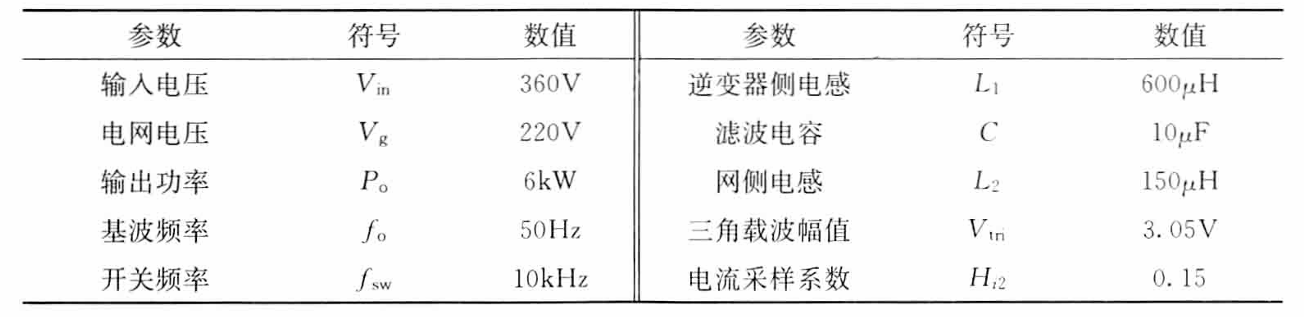

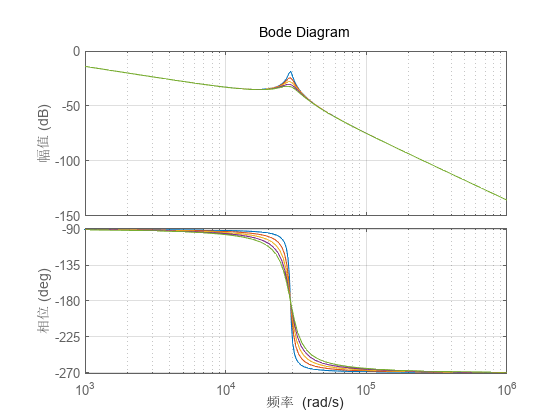

L1 = 600e-6;
C = 10e-6;
L2 = 150e-6;
Hi2 = 0.15;
Kpwm = 1;
Gi = 1;
Hi1 = 1;
for i = 1:5
    Hi1 = i;%1/R
    TA = tf([Hi2*Kpwm],[L1*L2*C L2*C*Hi1*Kpwm (L1+L2) 0])*Gi;
    bode(TA)
    hold on
end
grid on
hold off

Under PI controller


$$K_p \approx \frac{2\pi f_c(L_1+L_2)}{H_{i2}K_{PWM}}$$


$K_{iTfo} = \frac{4\pi^2 f_o(L_1+L_2)}{H_{i2}K_{PWM}} \sqrt{(10^{\frac{T_{fo}}{20}}fo )^2 - f_c^2}$   and   $K_{\mathrm{iPM}}=2\pi f_{\mathrm{c}}K_{\mathrm{p}}\frac{2\pi L_{1}(f_{\mathrm{r}}^{2}-f_{\mathrm{c}}^{2})-H_{i1}K_{\mathrm{PWM}}f_{\mathrm{c}}\tan\mathrm{PM}}{2\pi L_{1}(f_{\mathrm{r}}^{2}-f_{\mathrm{c}}^{2})\tan\mathrm{PM}+H_{i1}K_{\mathrm{PWM}}f_{\mathrm{c}}}$